# **GM(1,n)**

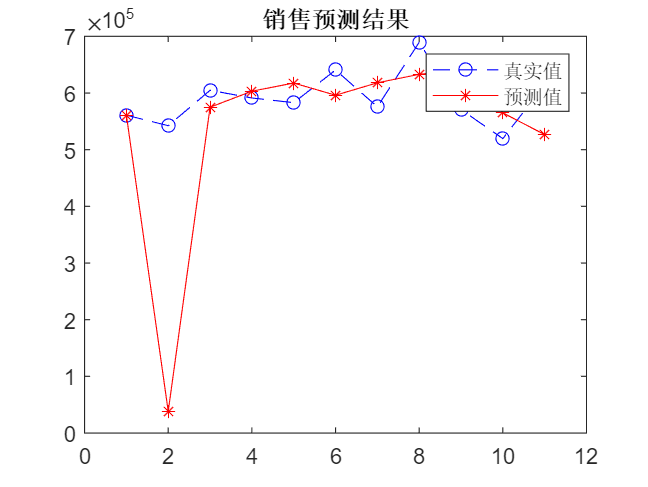

A=[560823,542386,604834,591248,583031,640636,575688,689637,570790,519574,614677];
x0=[104,101.8,105.8,111.5,115.97,120.03,113.3,116.4,105.1,83.4,73.3;
    135.6,140.2,140.1,146.9,144,143,133.3,135.7,125.8,98.5,99.8;
    131.6,135.5,142.6,143.2,142.2,138.4,138.4,135,122.5,87.2,96.5;
    54.2,54.9,54.8,56.3,54.5,54.6,54.9,54.8,49.3,41.5,48.9];
[n,m]=size(x0);
AGO=cumsum(A);
T=1;
x1=zeros(n,m+T);

for k=1:(m-1)
    Z(k)=(AGO(k)+AGO(k+1))/2; %Z(i)为xi(1)的紧邻均值生成序列
end
for i=1:n
    for j=1:m
        for k=1:j
            x1(i,j)=x1(i,j)+x0(i,k);%原始数据一次累加,得到xi(1)
        end
    end
end
x11=x1(:,1:m);
X=x1(:,2:m)';%截取矩阵
Yn =A;%Yn为常数项向量
Yn(1)=[]; %从第二个数开始，即x(2),x(3)...
Yn=Yn';
%Yn=A(:,2:m)';
B=[-Z',X];
C=((B'*B)\(B'*Yn))';%由公式建立GM(1,n)模型
a=C(1);
b=C(:,2:n+1);
F=[];
F(1)=A(1);
u=zeros(1,m);
for i=1:m
    for j=1:n
        u(i)=u(i)+(b(j)*x11(j,i));
    end
end
for k=2:m
    F(k)=(A(1)-u(k-1)/a)/exp(a*(k-1))+u(k-1)/a;
end
G=[];
G(1)=A(1);
for k=2:m
    G(k)=F(k)-F(k-1);%两者做差还原原序列，得到预测数据
end
t1=1:m;
t2=1:m;
plot(t1,A,'bo--');
hold on;
plot(t2,G,'r*-'); 
title('销售预测结果');
legend('真实值','预测值');